## Criando arquivo de áudio

load handel.mat;                                    % Retorna o sinal de um trecho de musica e sua taxa de amostragem

inicio = round(0 * Fs) + 1;                         % Define o inicio para o corte da música
fim = round(4 * Fs);                                % Define o final do corte

cuted_audio = y(inicio : fim, : );                  % Cria uma versão do sinal cortada

audiowrite("handel_cut.wav",cuted_audio,Fs);        % Cria um arquivo de áudio do sinal
clear;                                              % Limpando workspace para o próximo passo


## Filtrando o arquivo de áudio pelo método do janelamento

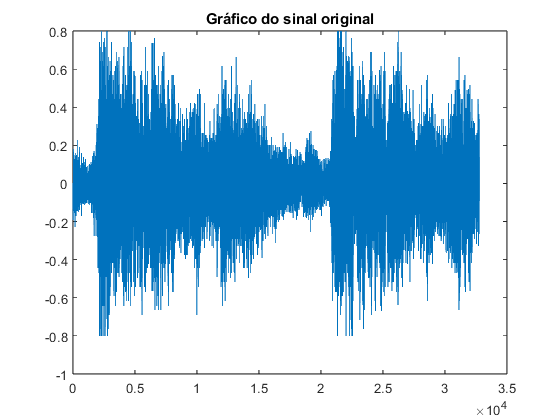

[x, fs] = audioread("handel_cut.wav");              % Lendo sinal do arquivo e sua respectiva taxa de amostragem
f1 = 1000;                                          % Frequência inicial da onda passante
f2 = 2000;                                          % Frequência final da onda passante
N = 50;                                             % Definindo quantidade de coeficientes
plot(x);title("Gráfico do sinal original");         % Mostrando gráfico do sinal original

### Utilizando janela gaussiana

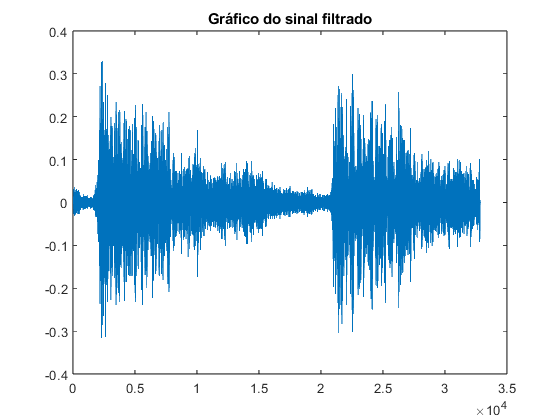

window = 3;                                         % Definindo tipo de janela como retangular
[h, H] = fir_janelamento(fs,f1,f2,N,window);        % Criando filtro com janela retangular
y = conv(x,h);                                      % Aplicando filtro ao sinal
plot(y);title("Gráfico do sinal filtrado");         % Mostrando gráfico do sinal após aplicar filtro

amp = 5;                                            % Definindo amplitude do sinal(volume)
y = y*amp;                                          % Aumentando amplitude do sinal para ficar melhor de se ouvir
audiowrite("handel_fil.wav",y,fs);                  % Criando arquivo de áudio com o sinal

sound(y,fs);                                        % Reproduzindo áudio do arquivo